% % This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,1,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
l_0 = sym('l','real');
l_=[l_0,l_0,l_0]' ;
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rpr';'xyx';sigmaD]

R2Robot = 3×3 char array
    'rpr'
    'xyx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;

z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% z.dhTable=dhTable
z.firstParam='alpha';
m_p=sym('m_p','real')

$$m\_p = m_{p}$$

I_p=sym('I_p','real')

$$I\_p = I_{p}$$

% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.opt_expr={[m(3),I(3)],[m(3)+m_p,I(3)+I_p]}

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: {[m3    I3]  [m3 + m_p    I3 + I_p]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
   

% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: {[m3    I3]  [m3 + m_p    I3 + I_p]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
   

% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Pc=Pc(1:2,:)
% z.g=z.g(1:2,:)
% J=jacobian(Pc(:,2),z.q)
% I_inv=pinv(J)
% M

% [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)

% % Msubs
% % % 
% % 
% % % PC_EEShort.J
% % % PC_EEShort.f

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: {[m3    I3]  [m3 + m_p    I3 + I_p]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
   

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{l_{1}}^{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,l_{1}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{l_{1}}^{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,l_{1}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} & \left(\frac{m_{3}}{2}+\frac{m_{p}}{2}\right)\,\left({{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+2\,\sin\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,q_{2}+{l_{1}}^{2}+{q_{2}}^{2}\right)+{{\dot{q}}_{2}}^{2}+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,l_{1}+2\,{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{3}\right)+q_{2}\,\sin\left(q_{3}\right)\right)\right)+\frac{{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}\,\left(I_{3}+I_{p}\right)}{2} \end{array}\right)$$

$$f = \left(\begin{array}{c} l_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ l_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

$$J = \left(\begin{array}{ccc} -l_{3}\,\sin\left(q_{1}+q_{3}\right)-q_{2}\,\cos\left(q_{1}\right)-l_{1}\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & -l_{3}\,\sin\left(q_{1}+q_{3}\right)\\ l_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & l_{3}\,\cos\left(q_{1}+q_{3}\right) \end{array}\right)$$

$$V = \left(\begin{array}{c} -\sin\left(q_{1}\right)\,\left({\dot{q}}_{2}+l_{1}\,{\dot{q}}_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ \cos\left(q_{1}\right)\,\left({\dot{q}}_{2}+l_{1}\,{\dot{q}}_{1}\right)-q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right) \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [2×3 sym]
              Pc: [3×3 sym]
              vc: [3×3 sym]
     f_derivated: [1×1 struct]
           f_dot: [2×1 sym]
          f_ddot: [2×1 sym]
          f_tdot: [2×1 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×3 sym]
               w: [3×3 sym]
               T: (m2*((dc2^2 - 2*dc2*q_2 + l1^2 + q_2^2)*q_dot_1^2 + 2*l1*q_dot_1*q_dot_2 + q_dot_2^2))/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2 + (I2*q_dot_1^2)/2 + (m3/2 + m_p/2)*(q_dot_1^2*(dc3^2 + 2*cos(q_3)*dc3*l1 + 2*sin(q_3)*dc3*q_2 + l1^2 + q_2^2) …
              Ti: [1×3 sym]
               M: [3×3 sym]


PC_EEShort = struct with fields:
              f: [2×1 sym]
              J: [2×3 sym]
    J_dot_short: [2×3 sym]
              V: [2×1 sym]
             Pc: [3×3 sym]
        Pc_ddot: []
        PTotali: [3×3 sym]


VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: (m3/2 + m_p/2)*(q_dot_1^2*(dc3^2 + 2*c3*dc3*l1 + 2*s3*dc3*q_2 + l1^2 + q_2^2) + q_dot_2^2 + dc3^2*q_dot_3^2 + q_dot_1*q_dot_2*(2*l1 + 2*c3*dc3) + 2*c3*dc3*q_dot_2*q_dot_3 + 2*dc3*q_dot_1*q_dot_3*(dc3 + c3*l1 + q_2*s3)) + (q_dot_1^2*(m1*dc1^2 …
    Ti: [1×3 sym]
     M: [3×3 sym]


PC_EE = struct with fields:
              f: [2×1 sym]
              J: [2×3 sym]
    J_derivated: [1×1 struct]
          J_dot: [2×3 sym]
         J_tdot: [2×3 sym]
           J_ps: [3×2 sym]
              V: [2×1 sym]


PCVar.Pc

$$ans = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & l_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & l_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 \end{array}\right)$$

PCVar.vc

$$ans = \left(\begin{array}{ccc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left(l_{1}\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\right)-{\dot{q}}_{2}\,\sin\left(q_{1}\right) & -{\dot{q}}_{2}\,\sin\left(q_{1}\right)-{\dot{q}}_{1}\,\left({\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sin\left(q_{1}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right)\right) & {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{1}\,\left({\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\right)+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

M=PCVar.M

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+I_{p}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{p}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{p}+m_{2}\,{q_{2}}^{2}+m_{3}\,{q_{2}}^{2}+m_{p}\,{q_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,m_{2}\,q_{2}+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{3}\right)+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{p}\,\cos\left(q_{3}\right)+2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,\sin\left(q_{3}\right)+2\,{\mathrm{dc}}_{3}\,m_{p}\,q_{2}\,\sin\left(q_{3}\right) & \sigma_{2} & \sigma_{1}\\ \sigma_{2} & m_{2}+m_{3}+m_{p} & \sigma_{3}\\ \sigma_{1} & \sigma_{3} & I_{3}+I_{p}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{p} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+I_{p}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{p}+{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{3}\right)+{\mathrm{dc}}_{3}\,l_{1}\,m_{p}\,\cos\left(q_{3}\right)+{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,\sin\left(q_{3}\right)+{\mathrm{dc}}_{3}\,m_{p}\,q_{2}\,\sin\left(q_{3}\right)\\ \sigma_{2}=l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{p}+{\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)+{\mathrm{dc}}_{3}\,m_{p}\,\cos\left(q_{3}\right)\\ \sigma_{3}={\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\,\left(m_{3}+m_{p}\right) \end{array}$$

% pinv(M)

PCVar.Ti(1)

$$ans = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

simplify(f)

$$ans = \left(\begin{array}{c} l_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ l_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


cac

Unrecognized function or variable 'cac'.

[cacsubs, dynamicParameters, acac] = getDynamicParameters3(cac,z.q,[q_dot],2)

Unrecognized function or variable 'cac'.

collect(PCVar.f_dot,l_0)
collect(PC_EEShort.f,l_0)
collect(PC_EEShort.J,l_0)
collect(f,l_0)
collect(J,l_0)
collect(PC_EEShort.J_dot_short,l_0)



## defining Control output

% lambda=sym('lambda','real')
% a_sym=sym('a','real')
% b_sym=sym('b','real')
% u_sym=lambda*a_sym+b_sym
% 
% 

m=[m;m_p]

$$m = \left(\begin{array}{c} m_{1}\\ m_{2}\\ m_{3}\\ m_{p} \end{array}\right)$$

## U_max definition

% U_max_=[15,10,10]'*pi
q_=[pi/4,0.25,-pi/4]'

q_ =     0.7854
    0.2500
   -0.7854


% q_dot_=0.5*[pi,pi,0]'
l_=[0.45,0.7,0.35]'

l_ =     0.4500
    0.7000
    0.3500


dc_=l_/2

dc_ =     0.2250
    0.3500
    0.1750


m_=[10,10,4,2]'

m_ =     10
    10
     4
     2


l_0_=1

l_0_ = 1

I_=m_(1:3).*dc_.^2

I_ =     0.5063
    1.2250
    0.1225


I=[I;I_p]

$$I = \left(\begin{array}{c} I_{1}\\ I_{2}\\ I_{3}\\ I_{p}\\ I_{p}\\ I_{p}\\ I_{p} \end{array}\right)$$

m=[m;m_p]
I_=[I_;0.01]

I_ =     0.5063
    1.2250
    0.1225
    0.0100


size(I)

ans =      4     1


[m_;[m_(1:3).*dc_.^2];0,01]

Error using sym/cat>checkDimensions (line 68)
CAT arguments dimensions not consistent.

Error in sym/cat>catMany (line 33)
[resz, ranges] = checkDimensions(sz,dim);

Error in sym/cat (<a href="m

% I=[I(1:3);I_p]
to_replace=[z.q;z.l;dc;m;I]

$$to\_replace = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3}\\ l_{1}\\ l_{2}\\ l_{3}\\ {\mathrm{dc}}_{1}\\ {\mathrm{dc}}_{2}\\ {\mathrm{dc}}_{3}\\ m_{1}\\ m_{2}\\ m_{3}\\ m_{p}\\ I_{1}\\ I_{2}\\ I_{3}\\ I_{p} \end{array}\right)$$

to_replace_=[q_;l_;dc_;m_;I_]

Error using sym/cat>checkDimensions (line 68)
CAT arguments dimensions not consistent.

Error in sym/cat>catMany (line 33)
[resz, ranges] = checkDimensions(sz,dim);

Error in sym/cat (<a href="m

m_=subs(M,to_replace,to_replace_)

Error using sym/subs>normalize (line 234)
Inconsistency between sizes of second and third arguments.

Error in sym/subs>mupadsubs (line 165)
[X2,Y2,symX,symY] = normalize(X,Y); %#ok

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('sym/subs', 'C:\Program Files\MATLAB\R2021b\toolbox\symbolic\symbolic\@sym\subs.m', 153)" style="font-weight:bol

## Replacing values

% J0_=subs(J,to_replace,to_replace_)
% p0_dot_=J0_*q_dot_
% f0_fot_=subs(PCVar.f_dot,to_replace,to_replace_)
% 
% J0_dot_=subs(PC_EE.J_dot,to_replace,to_replace_)
% J0_pinv_=pinv(J0_)
% h0_=J0_dot_*q_dot_
% 

## getting u

% a_=-J0_pinv_*J0_*q_dot_
% b_=-J0_pinv_*h0_
% a_=vpa(a_)
% b_=vpa(b_)
% 
% % with complete computations it follows manually

% a=sym('a',[z.n,1],'real');
% b=sym('b',[z.n,1],'real');
% U_max=sym('U_max',[z.n,1],'real');
% sim_lp_vars.a=a;
% sim_lp_vars.b=b;
% sim_lp_vars.U_min=-U_max;
% sim_lp_vars.U_max=U_max;
% 
% sim_lp_vars_.a=double(a_);
% sim_lp_vars_.b=double(b_);
% sim_lp_vars_.U_min=-U_max_;
% sim_lp_vars_.U_max=U_max_;
% % U_min=-U_max;
% [lambda_i,lambda_i_,lambda_]=lp_problems_solver(sim_lp_vars,sim_lp_vars_)
% 

% lambda_i_
% lambda_

% lambda_i(1)

## Replacing valeus for U0

% u=lambda*a+b
% u_=subs(u,[a;b;lambda],[a_;b_;lambda_])

% 
% p0_ddot_=-lambda_*p0_dot_
% vpa(p0_ddot_)

## Exercise 2

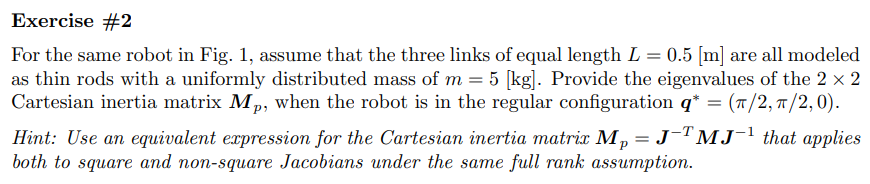

% % % close all
% % % % Lengths just to test
% % % d1_=10;
% % % d2_=10;
% % % a2_=10;
% % % % % De Luca's approach
% % %  links = [
% % %     Revolute('a', 0, 'alpha', -pi/2 ,'d', 1);
% % %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% % % %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% % %     ];
% % % % 
% % %  c600 = SerialLink(links);
% % %  c600.teach([0 0],'view','x');
% % % % c600.plot([0  pi/2 20 0],'view','x')
% % % clear

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)
% % [Pc,vc,w,T,Ti,M] = getGenericPC2_xyz(z)

% PCVar.Pc
% f
% % vc
% % simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))
% % Ti(1)
% % Ti(2)
% M=PCVar.M

## Replacing values

% % U_max=[15,10,10]'*pi
% % q_=[0,pi/2,pi/2]'
% % q_dot_=0.7*[pi,pi,0]'
% l_=[0.5,0.5,0.5]'
% dc_=l_/2
% m=5
% I_=(1/12)*m*(l_.^2)
% m_=[5,5,5]'
% % to_replace=[z.q;z.q_dot;z.l]
% % to_replace_=[q_;q_dot_;l_]
% 
% to_replace  =[z.l;z.dc;z.I;z.m]
% to_replace_ =[l_;dc_;I_;m_]

## Replacing values

% M_=subs(M,to_replace,to_replace_)
% J_=subs(J,to_replace,to_replace_)

## Replacing joints states

% q_=[pi/2,pi/2,0]'
% % q_dot_=0.7*[pi,pi,0]'
% 
% to_replace2=[z.q]
% to_replace2_=[q_]

% M2_=subs(M_,to_replace2,to_replace2_)
% J2_=subs(J_,to_replace2,to_replace2_)

## computation of M_p

% % M_p_=(J2_^(-1))'*M2_*(J2_^(-1))
% M_p_=pinv(J2_)'*M2_*(pinv(J2_))
% M_p2_=pinv(J2_*pinv(M2_)*J2_')
% 
% % M_p3_=pinv(J2_')*pinv(J2_*pinv(M2_))
% vpa(eig(M_p_))
% vpa(eig(M_p2_))


## Exercise 3

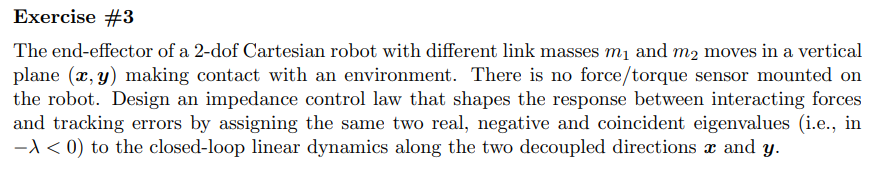

% % 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,1];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['pp';'xy';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Pc=Pc(1:2,:)
% z.g=z.g(1:2,:)
% J=jacobian(Pc(:,2),z.q)
% I_inv=pinv(J)
% M

% [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)

% % Msubs
% % % 
% % 
% % % PC_EEShort.J
% % % PC_EEShort.f

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

% [C,cac,Csubs] = getCs(M,z.q,z.q_dot)

% cac

% g_q
% U{:}

% % F_v=sym('F',[2,1],'real')
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,(g_q)],q,[q_dot.',g0],2)

% 
% % %complete model
% Msubs=All(:,1:z.n)
% gsubs=All(:,z.n+1)
% % Msubs*z.q_ddot+cac+F_v'*z.q_dot%=Tao
% Msubs*z.q_ddot+cac+gsubs%=Tao
% 

% M_inv=pinv(M)
% s=sym('s','real')
% lambda=sym('lambda','real')
% Dm=eye(n).* sym('D_m_',[n,1],'real')
% Km=eye(n).*sym('K_m_',[n,1],'real')
% 
% eig_mat= eye(n).*((s+lambda)^2)

% plant_s=eye(n).*s^2+M_inv*Dm*s+M_inv*Km

## solving equations

% solve(plant_s==eig_mat)